# Numerik Projekt: Flug zum Mars

clear; clc; close all;

%% Parameter für die Simulation definieren (Quelle: Wikipedia)
G = 6.67430e-11;       % Gravitationskonstante 
M_sonne = 1.9884e30;   % Masse der Sonne in kg


% Parameter Erde
radius_erde=6371*10^3;           %[m]
pos_erde = [149.6*10^9; 0; 0];
T_Erde = 365.25*24*3600;         %[s] 365.25=Umlaufzeit in Tagen
R_Erde = pos_erde(1);
M_erde  = 5.9722e24;             % Masse der Erde in kg

% Mars
radius_mars = 3.389*10^3         %[m]

radius_mars = 3389

pos_mars = [-227.9e9, 0, 0];
T_Mars = 687*24*3600;            %[s] 687=Umlaufzeit in Tagen ca.
R_Mars = norm(pos_mars(1));      
M_mars  = 6.39e23;

%% 2. Berechnung der Winkelgeschwindigkeiten aus den Umlaufdauern
% omega = 2 * pi / T
w_Erde = 2 * pi / T_Erde;
w_Mars = 2 * pi / T_Mars;

## Aufgabe 1: Plot: Modell des Sonnensystems

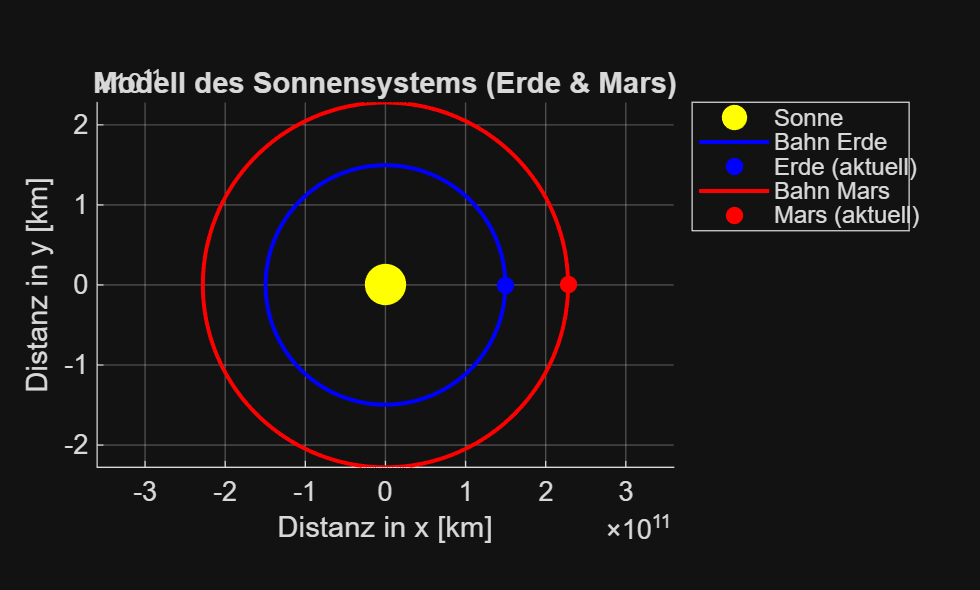

%Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:(1*24*3600):(730*24*3600); 

%% Berechnung der Bahnkurven als Kreisbahnen 
%% aus den Winkelgeschwindigkeiten der Planeten 
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

%% 5. Visualisierung der Flugbahnen
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

% Beschriftung
xlabel('Distanz in x [km]');
ylabel('Distanz in y [km]');
title('Modell des Sonnensystems (Erde & Mars)');
legend('Location', 'northeastoutside');

hold off;

## Aufgabe 2: Gravitationsfeld

% Beispielpunkt im Weltraum
pos = [1.4e11, 0, 0]

pos = 1.0e+11 *

    1.4000         0         0



%% Berechnung Gravitationsvektoren (Beschleunigung)
% Nur mit einfluss Sonne
g_sonne = gravitation_sonne(pos, G, M_sonne, [0, 0, 0])

g_sonne =    -0.0068         0         0



% Mit Einfluss Sonne und Planeten
g_system = gravitation_sonnensystem(pos, G, M_sonne, M_erde, M_mars, [0, 0, 0], pos_erde, pos_mars)

g_system =    -0.0068    0.0000    0.0000
   -0.0068         0         0
   -0.0068         0         0


## Aufgabe 3: Bahnkurve einer Sonde

% Parameter für die ode Funktion
tspan=[0 365*24*3600];

%Startwerte für ode
r0=[pos_erde(1)+radius_erde; 0; 0];
v0=[0;w_Erde*pos_erde(1)+15*10^3;0];
u0=[r0;v0];

### Nur mit Einfluss vom Gravitationsfeld Sonne:

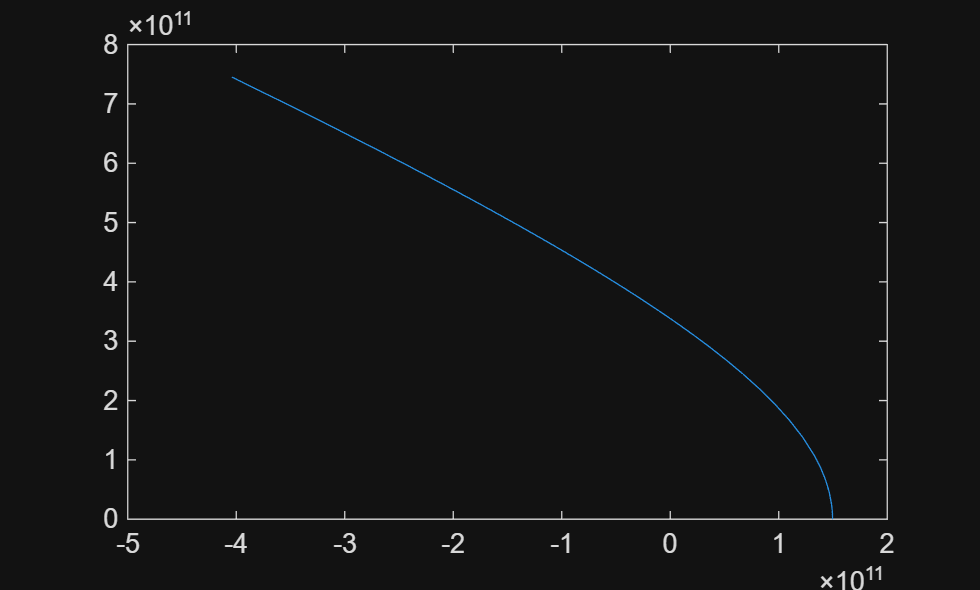

input_fuer_ode_sun=@(t,u) DGL_Sonne(t, u, G, M_sonne);
% Das muss so gemacht werden, da ode45 nur zwei Eingabewerte akzeptiert(t&u)

[t_erg_sun, u_erg_sun]=ode45(input_fuer_ode_sun,tspan,u0);
% t muss hier nur wegen Syntaxvorgabe von ode45

plot(u_erg_sun(:,1), u_erg_sun(:,2))

### Mit Einfluss von Sonne, Erde und Mars:

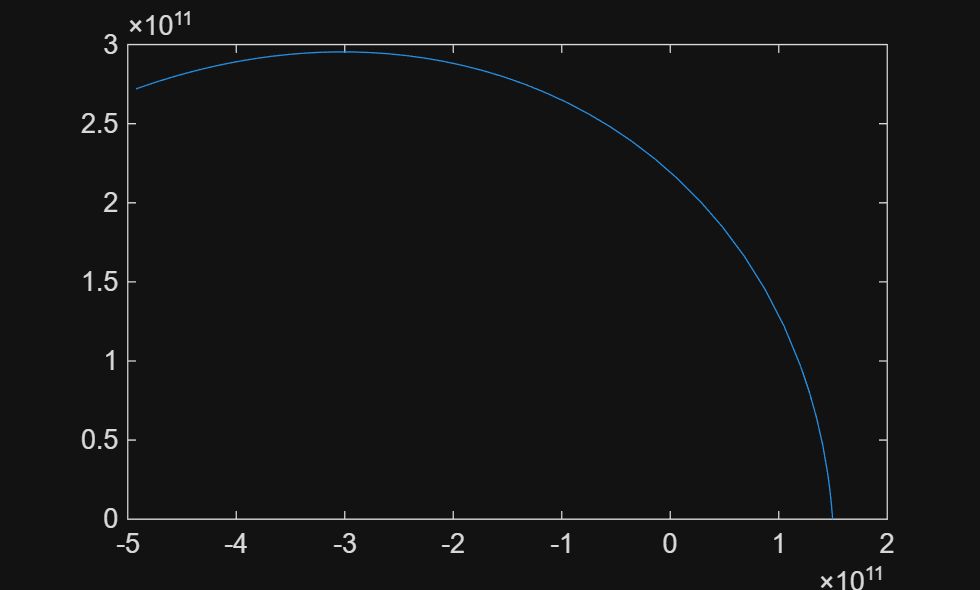

input_fuer_ode_sonnensystem=@(t,u) DGL_Sonnensystem(t, u, G, M_sonne, M_erde, M_mars, R_Erde, R_Mars, w_Erde, w_Mars);
%das muss so gemacht werden, da ode45 nur zwei Eingabewerte akzeptiert(t&u)

[t_erg_so_sys, u_erg_so_sys]=ode45(input_fuer_ode_sonnensystem,tspan,u0);

plot(u_erg_so_sys(:,1), u_erg_so_sys(:,2))

### Plot Zusammen:

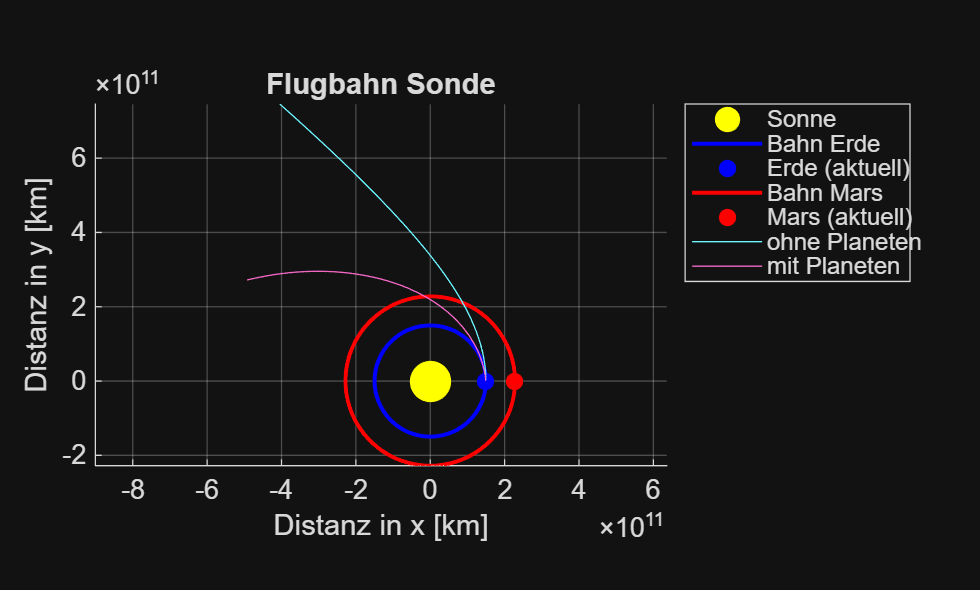

% Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:(1*24*3600):(730*24*3600); 

% Berechnung der Bahnkurven
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

% 5. Visualisierung
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

plot(u_erg_sun(:,1), u_erg_sun(:,2), 'DisplayName', 'ohne Planeten');
plot(u_erg_so_sys(:,1), u_erg_so_sys(:,2), 'DisplayName', 'mit Planeten');

% Beschriftung
xlabel('Distanz in x [km]');
ylabel('Distanz in y [km]');
title('Flugbahn Sonde');
legend('Location', 'northeastoutside');

hold off;

## Trajektorie 1:

Finden der Geschwindigkeit, um den Mars zu treffen

% Start-Schätzung
% wurde durch probieren ermittelt
v_guess = 6500; 

% alle Parameter der Optimierungs-Funktion festlegen, sodass sie
% nur mehr von v abhängig ist (v wird variiert)
% in optimerungs_func ist der Fehler (Abstand zwischen Mars und Sonde) in
% abhängigkeit von dem dazugehörigen v enthalten
optimierungs_func = @(v) ziel_funktion_mars(v, G, M_sonne, R_Erde, R_Mars, w_Erde, w_Mars, pos_erde, pos_mars, radius_erde);

% fminsearch sucht den kleinstmöglichsten Fehler, und gibt dann das
% dazugehöroge optimale v zurück
[v_opt, fehler_min] = fminsearch(optimierungs_func, v_guess);

fprintf('Optimale Startgeschwindigkeit: %.2f m/s\n', v_opt);

Optimale Startgeschwindigkeit: 6381.57 m/s


fprintf('Restlicher Abstand zum Mars: %.2f km\n', fehler_min/1000);

Restlicher Abstand zum Mars: 0.00 km



% Manuelle Simulation für den Plot
r0 = pos_erde;
v_erde_tangential = w_Erde * R_Erde;
v0 = [0; v_erde_tangential + v_opt; 0];
u0 = [r0; v0];

%options bricht ab wenn die Sonde die Marsbahn kreuzt
options = odeset('Events', @(t,u) event_marsbahn(t, u, R_Mars), 'RelTol', 1e-6);
tspan = [0 4*365*24*3600]; % Lange Laufzeit

[t_out, u_out, te, ue, ie] = ode45(@(t,u) DGL_Sonne(t, u, G, M_sonne), tspan, u0, options);

fprintf("Die Sonde braucht %.2f Tage um den Mars zu treffen", te/(24*3600));

Die Sonde braucht 851.13 Tage um den Mars zu treffen

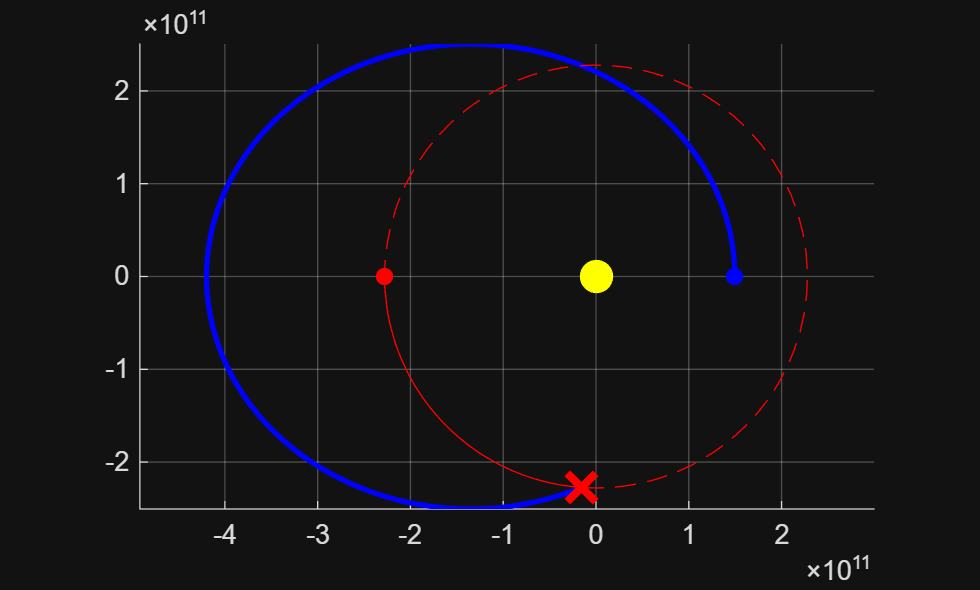


% Mars-Position über die Zeit berechnen
x_mars_plot = [];
y_mars_plot = [];
phi_mars_start = atan2(pos_mars(2), pos_mars(1));% von kartesisch zu polar

for k = 1:length(t_out)
    phi_now = phi_mars_start + w_Mars * t_out(k);% aktueller Winkel
    x_mars_plot(k) = R_Mars * cos(phi_now);% von polar zu kartesisch
    y_mars_plot(k) = R_Mars * sin(phi_now);
end

% Plotten
figure('Name', 'Fehler-Analyse');
hold on; axis equal; grid on;

% Sonne
plot(0,0, 'yo', 'MarkerFaceColor', 'y', 'MarkerSize', 12);

% Flugbahn Sonde
plot(u_out(:,1), u_out(:,2), 'b-', 'LineWidth', 2, 'DisplayName', 'Sonde');
% Startpunkt Sonde
plot(u_out(1,1), u_out(1,2), 'bo', 'MarkerFaceColor', 'b');
% Endpunkt Sonde (Schnittpunkt mit Mars-Orbit)
plot(ue(end,1), ue(end,2), 'bx', 'MarkerSize', 15, 'LineWidth', 3, 'DisplayName', 'Treffpunkt Orbit');

% Flugbahn Mars (während die Sonde fliegt)
plot(x_mars_plot, y_mars_plot, 'r--', 'DisplayName', 'Bewegung Mars');
% Startpunkt Mars
plot(x_mars_plot(1), y_mars_plot(1), 'ro', 'MarkerFaceColor', 'r');
% Endpunkt Mars (wo er ist, wenn die Sonde ankommt)
end_idx = length(t_out);
plot(x_mars_plot(end_idx), y_mars_plot(end_idx), 'rx', 'MarkerSize', 15, 'LineWidth', 3, 'DisplayName', 'Mars Position bei Ankunft');

## Trajektorie 2

Energiesparen durch Winkel

pos_erde_konj = [R_Erde; 0; 0];
pos_mars_konj = [-R_Mars; 0; 0]; 

%% Grobsuche (Grid Search): 
v_range = linspace(3000, 6000, 20);      
alpha_range = linspace(-60, 60, 20);     

best_fehler = inf;
best_v = 0;
best_alpha = 0;

% Wir erhöhen die Such-Zeit, falls die sparsame Bahn länger dauert
tspan_search = [0 5*365*24*3600]; 

% Grid Search Loop
% Grobe vorarbeit für fminsearch
for i = 1:length(v_range)
    for j = 1:length(alpha_range)
        v_test = v_range(i);
        alpha_test = deg2rad(alpha_range(j));
        
        fehler = ziel_funktion_mars_winkel([v_test, alpha_test], ...
            G, M_sonne, R_Erde, R_Mars, w_Erde, w_Mars, pos_erde_konj, pos_mars_konj, radius_erde);
        
        if fehler < best_fehler
            best_fehler = fehler;
            best_v = v_test;
            best_alpha = alpha_test;
        end
    end
end

fprintf('Grobsuche fertig. Bester Startpunkt: v=%.0f m/s, alpha=%.1f Grad\n', best_v, rad2deg(best_alpha));

Grobsuche fertig. Bester Startpunkt: v=4105 m/s, alpha=-34.7 Grad




% Feinoptimierung:
opt_func = @(p) ziel_funktion_mars_winkel(p, G, M_sonne, R_Erde, ...
    R_Mars, w_Erde, w_Mars, pos_erde_konj, pos_mars_konj, radius_erde);

% Wir starten beim besten Punkt aus dem Raster
[params_opt, fehler_opt] = fminsearch(opt_func, [best_v, best_alpha], options);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.614010 




v_beste = params_opt(1);
alpha_beste = params_opt(2);

fprintf('\n ERGEBNIS TRAJEKTORIE 2 \n');


 ERGEBNIS TRAJEKTORIE 2 


fprintf('Geschwindigkeit: %.2f m/s\n', v_beste);

Geschwindigkeit: 4153.68 m/s


fprintf('Abflugwinkel:    %.2f Grad\n', rad2deg(alpha_beste));

Abflugwinkel:    -36.02 Grad


fprintf('Fehler:          %.2f km\n', fehler_opt/1000);

Fehler:          0.00 km


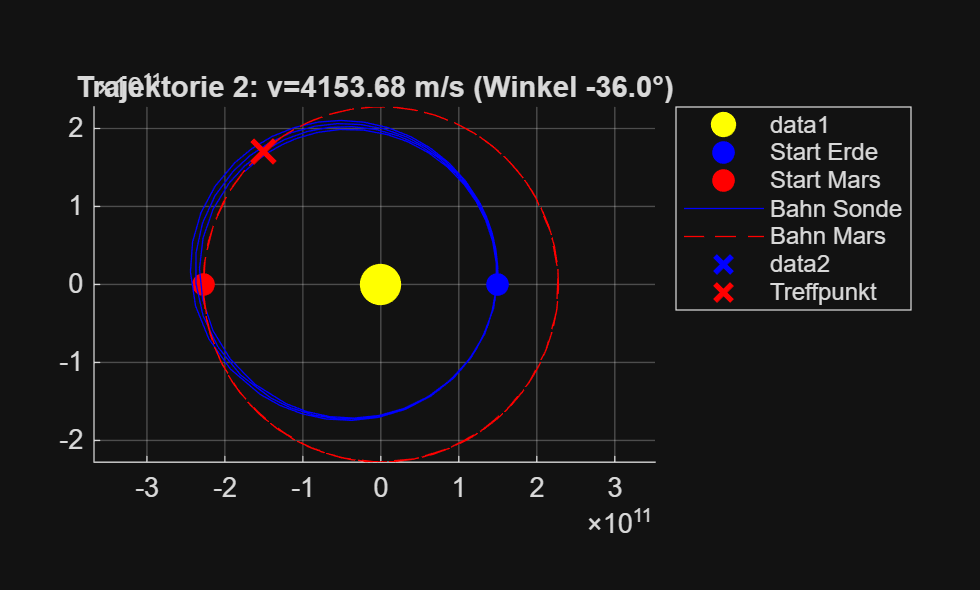


%% Visualisierung
r0 = pos_erde_konj;
v_erde_tang = w_Erde * R_Erde;
vx_start = -v_beste * sin(alpha_beste);
vy_start = v_erde_tang + v_beste * cos(alpha_beste);
u0 = [r0(1); r0(2); 0; vx_start; vy_start; 0];

%Hier simulieren wir 5 Jahre, um sicherzugehen, dass wir die Ankunft sehen
tspan_plot = [0 5*365*24*3600]; 
[t_out, u_out] = ode45(@(t,u) DGL_Sonne(t, u, G, M_sonne), tspan_plot, u0);

% Mars Position berechnen
phi_mars_start = atan2(pos_mars_konj(2), pos_mars_konj(1));
phi_mars_all = phi_mars_start + w_Mars * t_out;
x_mars_plot = R_Mars * cos(phi_mars_all);
y_mars_plot = R_Mars * sin(phi_mars_all);

% Treffpunkt finden
dx = u_out(:,1) - x_mars_plot;
dy = u_out(:,2) - y_mars_plot;
abstaende = sqrt(dx.^2 + dy.^2);
[min_dist, idx_treffer] = min(abstaende);

% Plotten
figure('Name', 'Trajektorie 2 - Optimiert');
hold on; grid on; axis equal;

plot(0, 0, 'yo', 'MarkerFaceColor', 'yellow', 'MarkerSize', 15); % Sonne
plot(pos_erde_konj(1), pos_erde_konj(2), 'bo', 'MarkerFaceColor', 'blue', 'MarkerSize', 8, 'DisplayName', 'Start Erde');
plot(pos_mars_konj(1), pos_mars_konj(2), 'ro', 'MarkerFaceColor', 'red', 'MarkerSize', 8, 'DisplayName', 'Start Mars');

plot(u_out(:,1), u_out(:,2), 'b-', 'DisplayName', 'Bahn Sonde');
plot(x_mars_plot, y_mars_plot, 'r--', 'DisplayName', 'Bahn Mars');

% Treffpunkt
plot(u_out(idx_treffer,1), u_out(idx_treffer,2), 'bx', 'MarkerSize', 12, 'LineWidth', 2);
plot(x_mars_plot(idx_treffer), y_mars_plot(idx_treffer), 'rx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Treffpunkt');

title(sprintf('Trajektorie 2: v=%.2f m/s (Winkel %.1f°)', v_beste, rad2deg(alpha_beste)));
legend('Location', 'bestoutside');
hold off;


fprintf('Flugdauer: %.1f Tage (%.1f Jahre)\n', t_out(idx_treffer)/(24*3600), t_out(idx_treffer)/(365*24*3600));

Flugdauer: 1281.2 Tage (3.5 Jahre)



fprintf('Flugdauer: %.1f Tage\n', t_out(idx_treffer)/(24*3600));

Flugdauer: 1281.2 Tage



function abstand_fehler = ziel_funktion_mars_winkel(params, G, M_sonne, R_Erde, R_Mars, w_Erde, w_Mars, start_pos_erde, start_pos_mars, radius_erde)
    v_boost = params(1);
    alpha = params(2);
    
    v_erde_tang = w_Erde * R_Erde;
    vx = -v_boost * sin(alpha);
    vy = v_erde_tang + v_boost * cos(alpha);
    
    u0 = [start_pos_erde(1) + radius_erde; start_pos_erde(2); start_pos_erde(3); vx; vy; 0]; 
    
    tspan = [0 5*365*24*3600]; 
    
    try
        [t_out, u_out] = ode45(@(t,u) DGL_Sonne(t, u, G, M_sonne), tspan, u0);
    catch
        abstand_fehler = 1e15;
        return;
    end
    
    phi_mars_start = atan2(start_pos_mars(2), start_pos_mars(1));
    phi_mars_all = phi_mars_start + w_Mars * t_out;
    
    mars_x = R_Mars * cos(phi_mars_all);
    mars_y = R_Mars * sin(phi_mars_all);
    
    dx = u_out(:,1) - mars_x;
    dy = u_out(:,2) - mars_y;
    abstaende = sqrt(dx.^2 + dy.^2);
    
    abstand_fehler = min(abstaende);
end

function abstand_fehler = ziel_funktion_mars(v_start_guess, G, M_sonne, R_Erde, R_Mars, w_Erde, w_Mars, start_pos_erde, start_pos_mars, radius_erde)
    
    % 1. Startbedingungen
    r0 = start_pos_erde + [radius_erde; 0; 0]; 
    v_erde_tangential = w_Erde * R_Erde;
    v0 = [0; v_erde_tangential + v_start_guess; 0];
    u0 = [r0; v0];
    
    % 2. Simulation
    % WICHTIG: Direction = 1 (von innen nach außen) ist korrekt.
    options = odeset('Events', @(t,u) event_marsbahn(t, u, R_Mars), 'RelTol', 1e-6, 'AbsTol', 1e-8);
    tspan = [0 3*365*24*3600]; % Zeitrahmen lang genug wählen
    
    [t_out, u_out, te, ue, ie] = ode45(@(t,u) DGL_Sonne(t, u, G, M_sonne), tspan, u0, options);
    
    % Fall A: Die Sonde war zu langsam und hat die Marsbahn NIE erreicht
    if isempty(te)
        % Wir berechnen, wie weit die Sonde maximal gekommen ist (Aphel)
        abstand_sonne = sqrt(u_out(:,1).^2 + u_out(:,2).^2 + u_out(:,3).^2);
        max_erreichte_distanz = max(abstand_sonne);
        
        % Der Fehler ist: Wie viel fehlt noch bis zum Mars-Radius?
        missing_distance = R_Mars - max_erreichte_distanz;
        
        % Wir addieren eine "Strafe" (z.B. 1 Milliarde km), damit dieser Fehler 
        % immer größer ist als ein echter Treffer, aber trotzdem kleiner wird, 
        % je mehr Gas wir geben.
        penalty_base = 1e11; 
        abstand_fehler = penalty_base + missing_distance;
        
        return; 
    end
    
    % Fall B: Die Sonde hat die Marsbahn gekreuzt (Event hat ausgelöst)
    % Jetzt machen wir die normale Berechnung wie vorher
    
    % Zeit beim Kreuzen
    t_kreuzung = te(end); % Falls mehrmals, nimm das letzte (sollte aber nur einmal sein wegen direction)
    pos_sonde_final = ue(end, 1:3)';
    
    % Wo ist der Mars zu diesem Zeitpunkt?
    phi_mars_start = atan2(start_pos_mars(2), start_pos_mars(1));
    phi_mars_end = phi_mars_start + w_Mars * t_kreuzung;
    
    pos_mars_final = [R_Mars * cos(phi_mars_end);
                      R_Mars * sin(phi_mars_end);
                      0];
                      
    % Fehler: Distanz zwischen Sonde und Mars
    abstand_fehler = norm(pos_sonde_final - pos_mars_final);
end


function [value, isterminal, direction] = event_marsbahn(t, u, R_Mars)
    % Aktueller Abstand der Sonde zur Sonne
    r_sonde = norm(u(1:3));

    % Event löst aus, wenn die Sonde den Mars trifft
    value = r_sonde - R_Mars;
    isterminal = 1;
    direction  = -1;  % bei Flug von innen nach außen (positiver Durchgang)
end

function du=DGL_Sonnensystem(t, u, G, M_sonne, M_erde, M_mars, R_Erde, R_Mars, w_Erde, w_Mars)
    
    du=zeros(6,1);   
    pos_sonne=[0; 0; 0];

    sonde_pos=u(1:3);
    v_sonde=u(4:6);

    % Berechnung der Bahnkurven (Trajektorien)
    % Erde
    x_Erde = R_Erde * cos(w_Erde * t);
    y_Erde = R_Erde * sin(w_Erde * t);
    
    % Mars
    x_Mars = R_Mars * cos(w_Mars * t);
    y_Mars = R_Mars * sin(w_Mars * t);
    
    pos_erde = [x_Erde; y_Erde; 0];
    pos_mars = [x_Mars; y_Mars; 0];

    %Gravitationsfeld der Sonne
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    %Berechnung Grevitationsfeld Erde
    r_vec_erde = sonde_pos - pos_erde;
    dist_erde = norm(r_vec_erde);
    g_erde = -G * M_erde * (r_vec_erde / dist_erde^3);

    % Berechnung Gravitationsfeldfeld Mars
    r_vec_mars = sonde_pos - pos_mars;
    dist_mars = norm(r_vec_mars);
    g_mars = -G * M_mars * (r_vec_mars / dist_mars^3);

    %% 4. Superposition (Vektoraddition)
    g_total = g_sonne + g_erde + g_mars;

    du=[v_sonde; g_total];
end

function du=DGL_Sonne(t, u, G, M_sonne)%nur mit Gravitationsfeld der Sonne

    pos_sonne = [0; 0; 0]; % Sonne im Ursprung des Koordinatensystems

    du=zeros(6,1);

    sonde_pos=u(1:3);
    v_sonde=u(4:6);
    
    %Gravitationsfeld der Sonne
    %Vektor von der Sonne zum Punkt
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    du=[v_sonde; g_sonne];%nachher g_total
end

function g = gravitation_sonne(u, G, M_sonne, pos_sonne) % ermittelt die Beschleunigung die die Gravitation der Sonne an einen beliebigen Punkt ausübt
    r_vec_sonne = u - pos_sonne;
    dist_sonne = norm(r_vec_sonne);

    g = -G * M_sonne * (r_vec_sonne / dist_sonne^3);
end

function g = gravitation_sonnensystem(u, G, M_sonne, M_erde, M_mars, pos_sonne, pos_erde, pos_mars)
    %Gravitationsfeld der Sonne
    r_vec_sonne = u - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
        
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    %Berechnung Grevitationsfeld Erde
    r_vec_erde = u - pos_erde;
    dist_erde = norm(r_vec_erde);
    g_erde = -G * M_erde * (r_vec_erde / dist_erde^3);

    % Berechnung Gravitationsfeldfeld Mars
    r_vec_mars = u - pos_mars;
    dist_mars = norm(r_vec_mars);
    g_mars = -G * M_mars * (r_vec_mars / dist_mars^3);

    %% 4. Superposition (Vektoraddition)
    g = g_sonne + g_erde + g_mars;
end